clear;clc;

%--------------------------------------------------------------------------
%   窗函数双路延迟时域抖动分析
%--------------------------------------------------------------------------
N = 256;
win = @bartlett;
wo = repmat(win(N),3,1);
wd = circshift(wo,128);
w = wo+wd;
w = w./max(w);                  %归一化处理
disp('最大值 最小值 波纹抖动')

最大值 最小值 波纹抖动


[max(w) min(w) max(w)-min(w)]

ans =      1     1     0


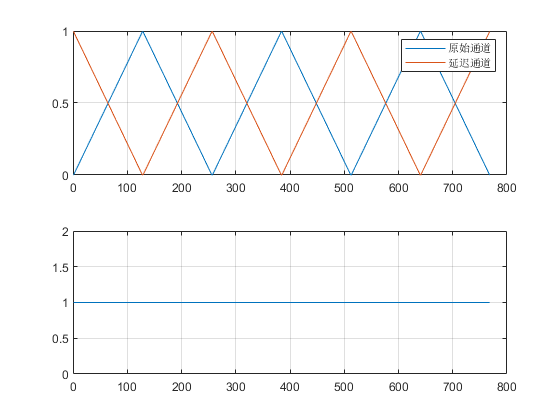

figure(1)
subplot(211);plot(wo);hold on;plot(wd);hold off;grid on;
legend('原始通道','延迟通道')
subplot(212);plot(w);grid on